此為DataGenerator.mlx輸出數據的圖片生成器

用法:

- 跑第一SECTION

- 若想生成三合一圖(角,彈性材料長度,扭矩)，跑第二SECTION

- 若想生成純扭矩圖，跑第三SECTION

- 檔案會生成在Moment 或 3in1資料夾中

- 在WINDOWS的檔案檢視器以時間序檢視，不然檔案會亂序

三合一圖生成器

載入數據及求出其長度

clear;
load MomentChangingLD260k0.5.mat;
dataLength = length(export);
sortAccordingToMtotalFitRMSE = true;



for j = 1:1
    
    if sortAccordingToMtotalFitRMSE==true
        i=export(1).idx(j);
    else
        i=j;
    end
    
    angleCount = length(export(i).thetad)
    
    fig1 = figure;
    
    fig1.Position = [0 0 1200 800];
    
    %***textbox***%
    dim = [.55 .4 .05 .05];
    str = "D = " + export(i).d + "  "  + "k= " + export(i).k + "  " +"l= " ...
        + export(i).l+ "\n" +...
        "RMSE= " + export(i).RMSE ...
        + "\nMAE=" +export(i).MAE...
        + "\n"+"fit RMSE="+export(i).MtotalfitRMSE ...
        +"\n" + "fitSlope= " +export(i).fitSlope...
        +"\nMaxLP1P2=" + export(i).maxLP1iP2i(1) + " when theta="+ export(i).thetad(export(i).maxLP1iP2i(2))...
        +"\nLP1P2MaxExtendRatio=" +export(i).maxInitialRatio;
    str = compose(str);
    an = annotation('textbox',dim,'String',str,'FitBoxToText','on');
    an.FontSize = 15;
    %*************%
    
    tiledlayout(2,2);
    
    nexttile;
    
    plot(export(i).thetad, export(i).phiid, 'DisplayName',"phi"); hold on;
    title("\phi with respect to \theta when D = " + export(i).d);
    xlabel("\theta");
    ylabel("\phi");
    axis([-30 70 -0 180]);
    legend;
    
    
    
    %**************************
    nexttile;
    plot(export(i).thetad, export(i).LP1iP2i, 'DisplayName',"Length of L1L2"); hold on;
    title("LP1P2 with respect to \theta when D = " + export(i).d);
    xlabel("\theta");
    ylabel("LP1P2(mm)");
    %     axis([-70 70 240 1000]);
    legend;
    
    %*********************************
    nexttile;
    plot(export(i).thetad, export(i).Mg, 'k-', 'DisplayName',"Mg"); hold on;
    plot(export(i).thetad, export(i).Mfi, 'r-', 'DisplayName',"Mfi"); hold on;
    plot(export(i).thetad, export(i).Mtotal, 'b-', 'DisplayName',"Mtotal"); hold on;
    plot(export(i).thetad, export(i).FittedLine, 'g--', 'DisplayName', 'linear fit of Mtotal'); hold on;
    yline(0);
    %     legend;
    
    axis([-30 70 -4*(10^4) 6*(10^4)]);
    title("Moments at O4' with respect to \theta when D = " + export(i).d);
    xlabel("\theta");
    ylabel("M(N/mm)");
    
    hold off;
    
    if ~exist(pwd + "\3in1", 'dir')
        mkdir(pwd + "\3in1")
    end
    saveas(fig1, pwd + "\3in1" + "\3in1 D" + export(i).d + " k" + export(i).k + "l"+export(i).l+"fitRMSE="+export(i).MtotalfitRMSE+".png");
end

angleCount = 81

力矩圖生成器

載入數據及求出其長度

clear;
load MomentChangingLD260k0.5.mat;
dataLength = length(export);
sortAccordingToMtotalFitRMSE = false;
markMax=true;
showSlope=true;
for j= 1:length(export)

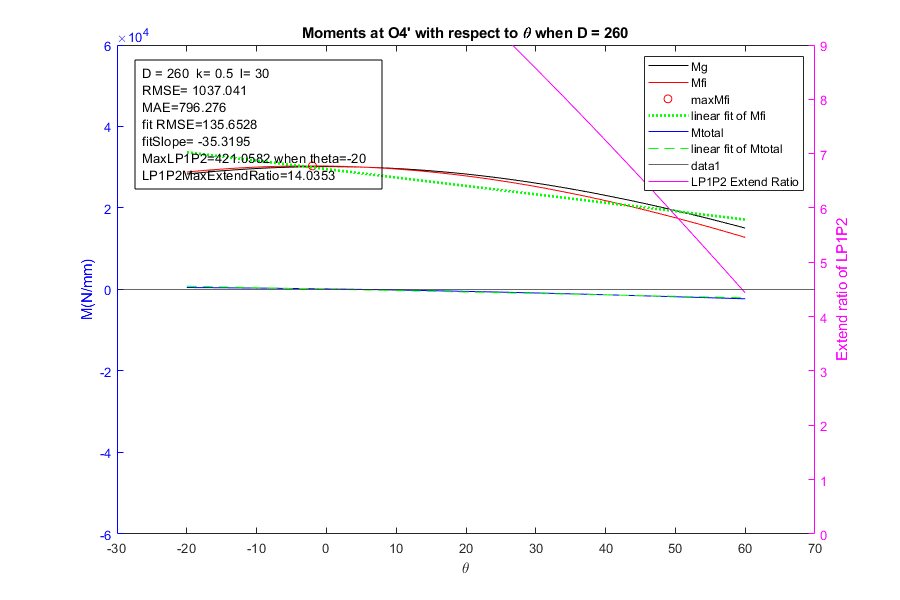

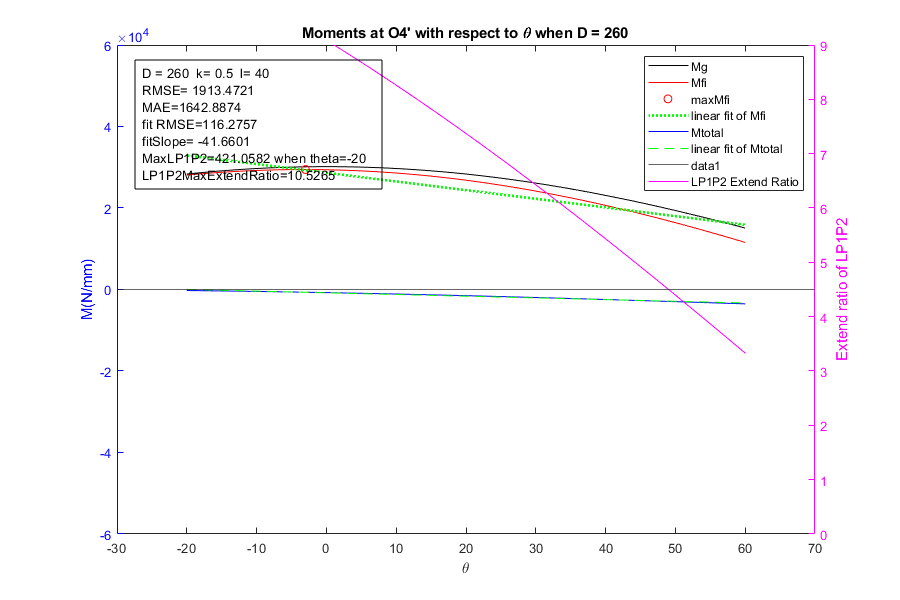

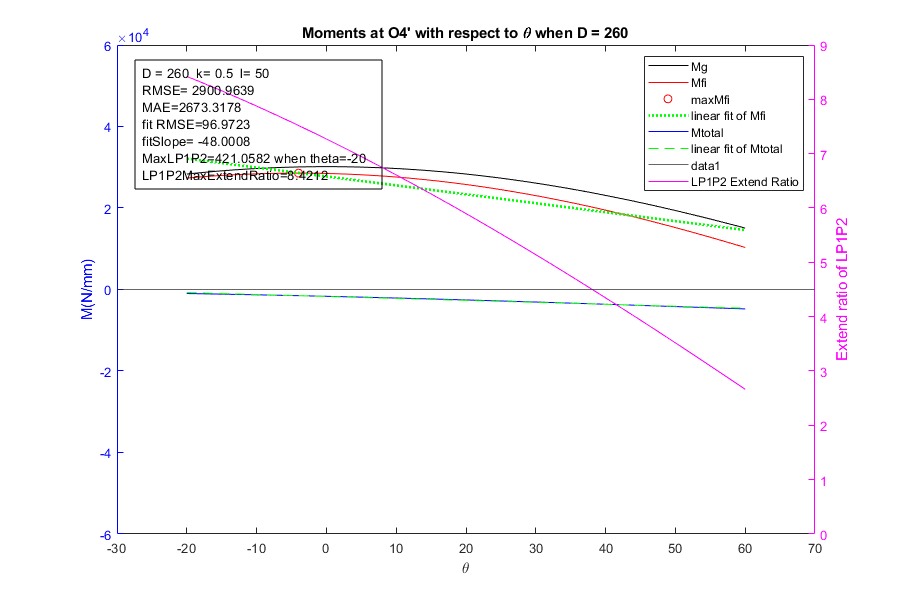

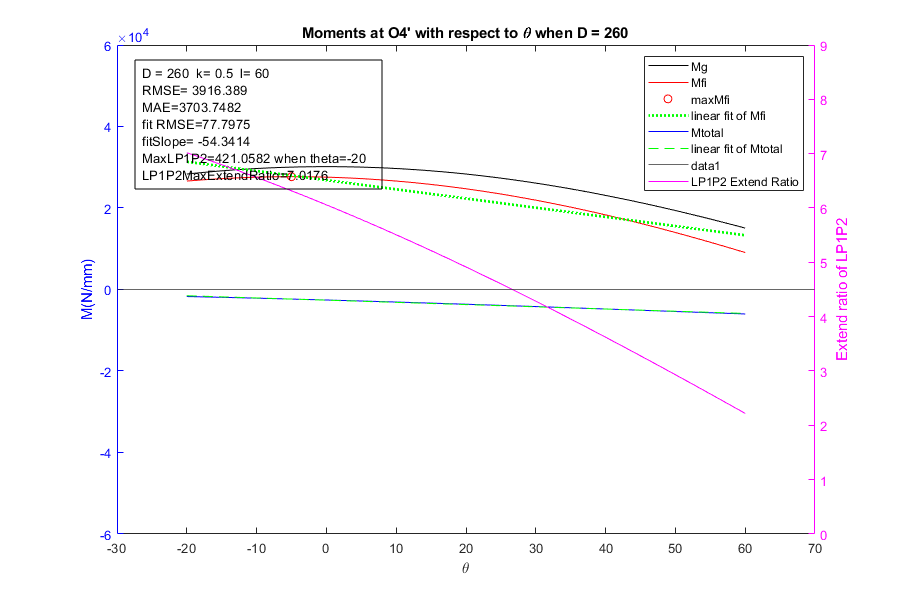

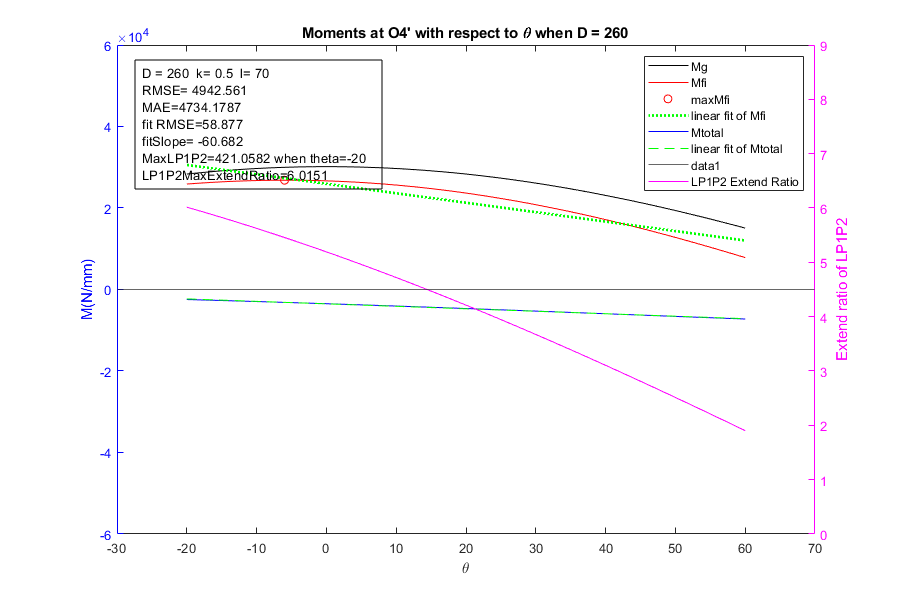

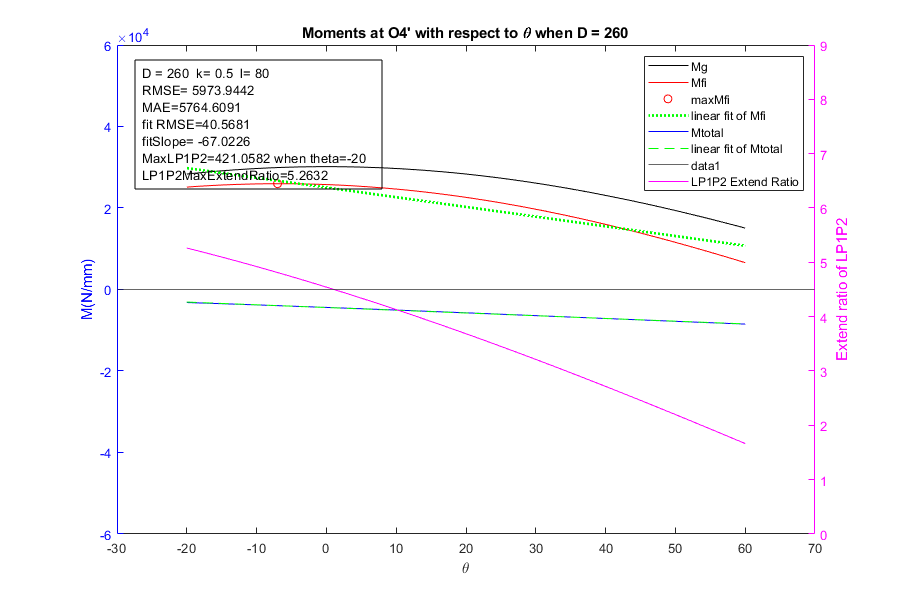

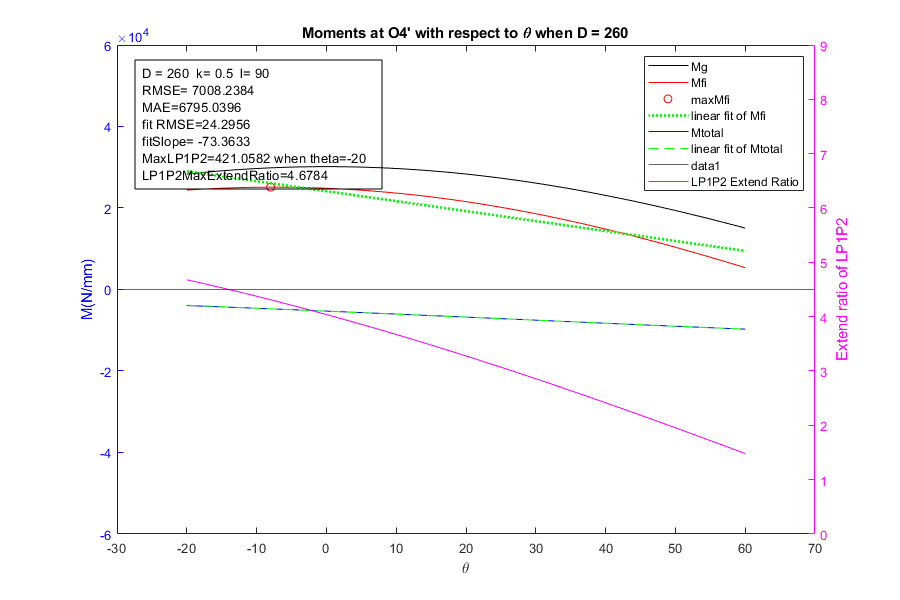

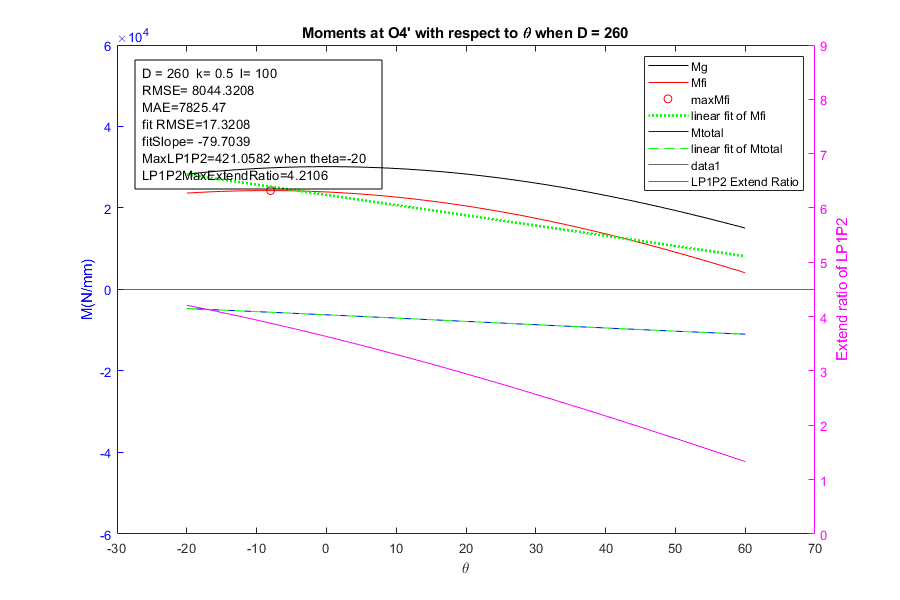

    
    if sortAccordingToMtotalFitRMSE==true
        i=export(1).idx(1);
    else
        i=j;
    end
    
    angleCount = length(export(i).thetad);
    
    fig1 = figure;
    
    fig1.Position = [0 0 900 600];
    
    colororder({'b','m'});
    
    yyaxis left; % left axis
    plot(export(i).thetad, export(i).Mg, 'k-', 'DisplayName',"Mg"); hold on;
    
    plot(export(i).thetad, export(i).Mfi, 'r-', 'DisplayName',"Mfi"); hold on;
    if markMax==1
        [~,imx]=max(export(i).Mfi(:));
        plot(export(i).thetad(imx), export(i).Mfi(imx),'or','DisplayName', 'maxMfi'); hold on    
    end
    if showSlope==1
        p = polyfit(export(i).thetad, export(i).Mfi,1);
        plot(export(i).thetad, polyval(p,export(i).thetad), ':g', "DisplayName","linear fit of Mfi", "LineWidth",2);
    end
    
    plot(export(i).thetad, export(i).Mtotal, 'b-', 'DisplayName',"Mtotal"); hold on;
    plot(export(i).thetad, export(i).FittedLine, 'g--', 'DisplayName', 'linear fit of Mtotal'); hold on;
    yline(0);
    
    axis([-30 70 -6*(10^4) 6*(10^4)]);
    title("Moments at O4' with respect to \theta when D = " + export(i).d);
    xlabel("\theta");
    ylabel("M(N/mm)");
    
    
    yyaxis right;
    plot(export(i).thetad, export(i).extendRatio,"DisplayName","LP1P2 Extend Ratio");
    ylabel("Extend ratio of LP1P2");
    axis([-30 70 0 9]);
    
    
    legend;
    
    
    %***textbox***%
    dim = [.15 .85 .05 .05];
    str = "D = " + export(i).d + "  "  + "k= " + export(i).k + "  " +"l= " ...
        + export(i).l+ "\n" +...
        "RMSE= " + export(i).RMSE ...
        + "\nMAE=" +export(i).MAE...
        + "\n"+"fit RMSE="+export(i).MtotalfitRMSE ...
        +"\n" + "fitSlope= " +export(i).fitSlope...
        +"\nMaxLP1P2=" + export(i).maxLP1iP2i(1) + " when theta="+ export(i).thetad(export(i).maxLP1iP2i(2))...
        +"\nLP1P2MaxExtendRatio=" +export(i).maxInitialRatio;
    str = compose(str);
    annotation('textbox',dim,'String',str,'FitBoxToText','on');
    %*************%
    
    hold off;
    
    if ~exist(pwd + "\Moment", 'dir')
        mkdir(pwd + "\Moment")
    end
    saveas(fig1, pwd + "\Moment" + "\Moment D" + export(i).d + " k" + export(i).k + "l"+export(i).l+"fitRMSE="+export(i).MtotalfitRMSE+"fitSlope="+export(i).fitSlope+".png");
end